clear all

load 'D:\Jazmin\Multichannel Data Tanks\Cortex\NormalizedIndexesTable_MUA.mat';
load 'D:\Jazmin\Multichannel Data Tanks\Cortex\SignificanceWindowTable_MUA.mat'; %The matrix obtained from the fuction ExtractMatFiles.m
load 'D:\Jazmin\Multichannel Data Tanks\Cortex\NormalizedIndexesTable.mat';
load 'D:\Jazmin\Multichannel Data Tanks\Cortex\SignificanceWindowTable.mat';
rangoY = [0 250]; % Y-axis range

SignificanceWindowTable = [SignificanceWindowTableMUA;SignificanceWindowTable];
NormalizedIndexesTable = [NormalizedIndexesTableMUA;NormalizedIndexesTable];

%Bootstrapping significance

Path = 'C:\SortingFolder\HIP\CSI_Boottstrap.xlsx';

% Import table
HIP_Multi  = readtable(Path);
HIParray = table2array(HIP_Multi(:,["CSI","Rango_1","Rango_2"]));
% HIParray(any(isnan(HIParray), 2), :) = [];

n=0;
m=0;
for i = 1:size(HIParray,1)
    if HIParray(i,2)<0 && HIParray(i,3)>0
        n = n + 1;
        NonSignificantAll(n,1) = i;
    else
        m = m + 1;
        SignificantAll(m,1) = i;
    end
end

% Significance 
n= 1;
for i = 1: size(SignificanceWindowTable,1)
    if (SignificanceWindowTable.SignificanceDEV1(i,1) + SignificanceWindowTable.SignificanceDEV2(i,1)) > 1
        SIscatterIndx(n,1)=i;
        n = n + 1;
    end
 end

%SI
figure
%Create histogram
scatter(NormalizedIndexesTable.SI1(SIscatterIndx,1),NormalizedIndexesTable.SI2(SIscatterIndx,1),'filled', 'MarkerFaceColor','#990033');
xlim([-1 1]);
ylim([-1 1]);
title('SI');
xlabel('SI F1');
ylabel('SI F2');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan")

SI_Mean = 0.2686

SI_std = std([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SIscatterIndx,1);NormalizedIndexesTable.SI2(SIscatterIndx,1)],1))*2)

err_SI = 0.0088

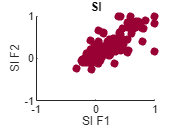


%Save figure
cd 'D:\Jazmin\Multichannel Data Tanks\Cortex\SI'
saveas(gcf,'SI_ALL.pdf');
saveas(gcf,'SI_ALL.tif');

saveas(gcf,'SI_ALL.fig');

% Significance SI Histogram
n= 1;
m= 1;
for i = 1: size(SignificanceWindowTable,1)
    if SignificanceWindowTable.SignificanceDEV1(i,1) > 0
        SI1HistIndx(n,1)=i;
        n = n + 1;
    end
    if SignificanceWindowTable.SignificanceDEV2(i,1) > 0
        SI2HistIndx(m,1)=i;
        m = m + 1;
    end 
 end

% SI
figure
%Create histogram
histogram([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim([0 250]);
xline(0,'LineWidth',2);
title('SI');
xlabel('SI index');
ylabel('repetitions');

%Calculating the mean and error
SI_Mean = mean([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan")

SI_Mean = 0.2505

SI_std = std([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],"omitnan");
err_SI = SI_std / sqrt((size([NormalizedIndexesTable.SI1(SI1HistIndx,1);NormalizedIndexesTable.SI2(SI2HistIndx,1)],1))*2)

err_SI = 0.0079

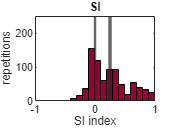

xline(SI_Mean,'LineWidth',2.5);

%Save figure
cd 'D:\Jazmin\Multichannel Data Tanks\Cortex\SI';
saveas(gcf,'SI_HIST_ALL.pdf');
saveas(gcf,'SI_HIST_ALL.tif');

saveas(gcf,'SI_HIST_ALL.fig');

% CSI
figure
%Create histogram
histogram(NormalizedIndexesTable.CSI(SIscatterIndx,1),'BinWidth',0.1, 'FaceColor','#990033','FaceAlpha',1);
xlim([-1 1]);
ylim(rangoY);
xline(0,'LineWidth',2);
title('CSI');
xlabel('CSI index');
ylabel('repetitions');

%Calculating the mean and error
CSI_Mean = mean(NormalizedIndexesTable.CSI(SIscatterIndx,1))

CSI_Mean = 0.2692

CSI_std = std(NormalizedIndexesTable.CSI(SIscatterIndx,1));
err_CSI = CSI_std / sqrt(size(NormalizedIndexesTable.CSI(SIscatterIndx,1),1))

err_CSI = 0.0170

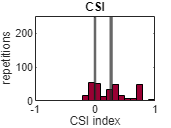

xline(CSI_Mean,'LineWidth',2.5);

%Save figure
cd 'D:\Jazmin\Multichannel Data Tanks\Cortex\CSI';
saveas(gcf,'CSI_ALL.pdf');
saveas(gcf,'CSI_ALL.tif');

saveas(gcf,'CSI_ALL.fig');

% iMM
iMMcasc = cat(1,NormalizedIndexesTable.iMM1ca(SI1HistIndx,1),NormalizedIndexesTable.iMM2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iMMcasc,'BinWidth',0.1,'FaceColor','#EA005F','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iMM');
xlabel('iMM index');
ylabel('repetitions');

%Calculating the mean and error
iMMcasc_Mean = nanmean(iMMcasc)

iMMcasc_Mean = 0.2696

iMMcasc_std = nanstd(iMMcasc);
err_iMMcasc = iMMcasc_std / sqrt(size(iMMcasc,1))

err_iMMcasc = 0.0118

xline(iMMcasc_Mean,'LineWidth',2.5);

[p_iMM_sig h] = signrank(iMMcasc)

p_iMM_sig = 6.4530e-69

h = logical
   1


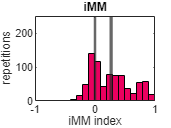


%Save figure
PathiMM = 'D:\Jazmin\Multichannel Data Tanks\Cortex\iMM';
cd (PathiMM);
saveas(gcf,'iMM_ALL.pdf');
saveas(gcf,'iMM_ALL.tif');

saveas(gcf,'iMM_ALL.fig');

% iPE CA1
iPEcasc = cat(1,NormalizedIndexesTable.iPE1ca(SI1HistIndx,1),NormalizedIndexesTable.iPE2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iPEcasc,'BinWidth',0.1,'FaceColor','#FF6600','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iPE');
xlabel('iPE index');
ylabel('repetitions');

%Calculating the mean and error
iPEcasc_Mean = nanmean(iPEcasc)

iPEcasc_Mean = 0.2527

iPEcasc_std = nanstd(iPEcasc);
err_iPEcasc = iPEcasc_std / sqrt(size(iPEcasc,1))

err_iPEcasc = 0.0115

xline(iPEcasc_Mean,'LineWidth',2.5);

[p_iPE_sig h] = signrank(iPEcasc)

p_iPE_sig = 5.3714e-70

h = logical
   1


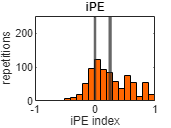


%Save figure
cd 'D:\Jazmin\Multichannel Data Tanks\Cortex\iPE';
saveas(gcf,'iPE_ALL.pdf');
saveas(gcf,'iPE_ALL.tif');

saveas(gcf,'iPE_ALL.fig');

% iRS CA1
iRScasc = cat(1,NormalizedIndexesTable.iRS1ca(SI1HistIndx,1),NormalizedIndexesTable.iRS2cd(SI2HistIndx,1));
figure
%Create histogram
histogram(iRScasc,'BinWidth',0.1,'FaceColor','#0099CC','FaceAlpha',1);
xlim([-1 1]);
ylim([rangoY]);
xline(0,'LineWidth',2);
title('iRS');
xlabel('iRS index');
ylabel('repetitions');


%Calculating the mean and error
iRScasc_Mean = nanmean(iRScasc)

iRScasc_Mean = 0.0169

iRScasc_std = nanstd(iRScasc);
err_iRScasc = iRScasc_std / sqrt(size(iRScasc,1))

err_iRScasc = 0.0070

xline(iRScasc_Mean,'LineWidth',2.5);

[p_iRS_sig h] = signrank(iRScasc)

p_iRS_sig = 0.0464

h = logical
   1


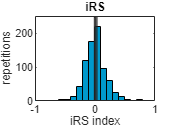


%Save figure
cd 'D:\Jazmin\Multichannel Data Tanks\Cortex\iRS';
saveas(gcf,'iRS_ALL.pdf');
saveas(gcf,'iRS_ALL.tif');

saveas(gcf,'iRS_ALL.fig');
